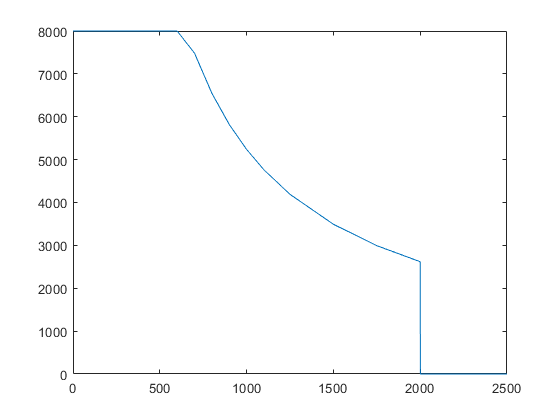

Tmax = 8000*1.36;
Pmax = 1000*746;
spdMax = 2000;
spdVec = [0 600 700 800 900 1000 1100 1250 1500 1750 2000 2001 2500];
spdRadS = spdVec*pi/30;

Trq_PowerLimit = Pmax./spdRadS;
TrqVec = min(repmat(Tmax,1,numel(spdVec)),Trq_PowerLimit);
TrqVec(spdVec > spdMax) = 0;
plot(spdVec,TrqVec/1.36);